# CS3200 Introduction to Scientific Computing

## Assignment #2

Assigned: 1/31/2022

Due: 02/14/2022

Author: Robert Li u1212360

## Problem 1: Interpolation of a Random Function

%Write your code for Problem 1 here
% clear all, close all, clc, clf
% syms y(x)
% y(x) = random_poly;
% w = 0.5:0.01:5.5;
% v = double(y(w));
% 
% for n = 1:10
%     plot(w,v,"LineWidth",3);
%     xPosition = linspace(0.5,5.5,n+1);
%     yPositon = y(xPosition);
%     hold on;
%     plot(xPosition,yPositon,'o', 'Linewidth', 1.5, 'MarkerSize', 7);
%     poly_y = polyinterp(xPosition,yPositon,w);
%     plot(w,poly_y,'Linewidth',1.5);
%     xlim([0 6]);
%     legend('true values', 'data point', 'Interpolated values');
%     pause(0.5);
%     hold off;
% end    

Write your Observations for Problem 1 here

(f) The approximation cannot always get the exact graph we want, always contain some erros. By increasing the n, my conclusion is we can increse the possibility to get the graph we need with less error. By decreasing the n, we have very big chance to get huge result gap(the graph is not preciece.). After all, as the n get larger, we will get less error for predicting the graph, but it always contain fault area.

(g) O(n^3) for Vandermonde interpolation

    O(n^2) for Lagrange Interpolation

    O(n) for Barycentric Interpolaion

## Problem 2: Understanding L1, L2, and Linf Norms

%Write your code for Problem 2 here
clear all, close all, clc, clf
a = 5;
b = 6;
x = [a,b];

x_L1 = [0,a];
y_L1 = [0,0];

x2_L1 = [a,a];
y2_L1 = [0,b];

plot(x_L1,y_L1,'red');
hold on;
plot(x2_L1,y2_L1,'red');
L2 = norm(x)

L2 = 7.8102

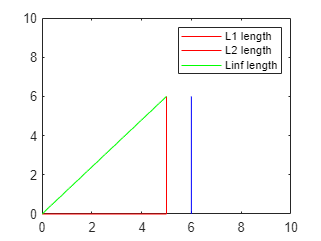

x_L2 = [0,a];
y_L2 = [0,b];
plot(x_L2,y_L2,'green');

x_L3 = [b,b];
y_L3 = [0,b];
plot(x_L3,y_L3,'blue')
legend('L1 length', 'L2 length', 'Linf length');
xlim([0.000 10.000])
ylim([0.00 10.0])

Write your Observations for Problem 2 here

(d)L1 is the largest in all the case.

(e)As p increse,the value of it decrease

## Problem 3: Runge's phenomenon & Chebyshev nodes

%Write your code for Problem 3 here
clear all, close all, clc, clf
% plot the runge function
syms f(x)
f(x) = 1/(1+25*x^2);
np = 1000;
xVal = (-1:1/np:1);
res = double(f(xVal));
plot(xVal,res);

% plot runge function with different degree
hold on
for n = [4,8,12]
    val = linspace(-1,1,n);
    k = polyinterp(val,f(val),xVal);
    plot(xVal,k,'linewidth',1.5);
    %calculating the L1 L2 Linf
    err = res - k;
    L1 = norm((err),1);
    L2 = norm(err);
    Linf = norm((err),inf);
    fprintf("n = %d",n)
    fprintf("L1 = %0.5f",L1)
    fprintf("L2 = %0.5f",L2)
    fprintf("Linf = %0.5f\n",Linf)
end

n = 4

L1 = 313.15135

L2 = 10.90573

Linf = 0.70701


n = 8

L1 = 171.04453

L2 = 4.60434

Linf = 0.24736


n = 12

L1 = 181.26587

L2 = 7.34379

Linf = 0.55676


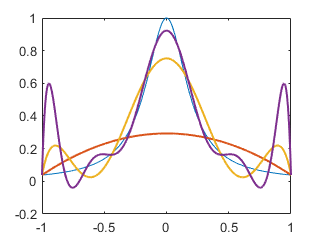

hold off


plot(xVal, res);
hold on
% try again with different loop
for n = [4, 8, 12, 16, 24]
 cheb = zeros(1,n);
 for k = 1:n
 cheb(k) = cos((2*k-1)/(2*n)*pi);
 end
 k = polyinterp(cheb, f(cheb), xVal);
 plot(xVal, k,'linewidth',1.5);
 err1 = res - k;
 errL1 = norm((err1), 1);
 errL2 = norm(err1);
 errLinf = norm((err1), inf);
 fprintf("n = %d", n)
 fprintf("errL1 = %0.5f",errL1)
 fprintf("errL2 = %0.5f ",errL2)
 fprintf("errLinf = %0.5f\n",errLinf)
end

n = 4

errL1 = 301.37831

errL2 = 11.59647 

errLinf = 0.75030


n = 8

errL1 = 141.28568

errL2 = 5.30837 

errLinf = 0.39174


n = 12

errL1 = 64.32769

errL2 = 2.34175 

errLinf = 0.18276


n = 16

errL1 = 29.10416

errL2 = 1.04646 

errLinf = 0.08311


n = 24

errL1 = 5.94069

errL2 = 0.21260 

errLinf = 0.01698


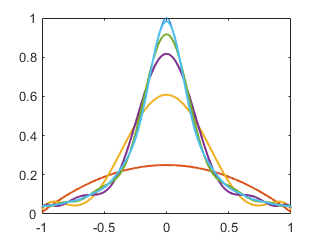

hold off

Write your Observations for Problem 3 here

By changing the loop length, we got the errors for L smaller as the n increase, I think it because the loop lengh increase, the model learn to predict it more preciecely.

## Problem 4: Piecewise **Interpolation of Cryptocurrency data using cubic splines**:

#### Data Import:  This part has been done for you.  You should change the path below to reflect the path of the bitcoinHist.csv.  Read through the section on working with date data so that you understand how to use it.

clear all, close all, clc, clf

% First Upload the data
% set the path of the file you want to upload here
addpath("/Users/10679/user/")
% import the csv file here and save to variable name ncount
bitcoin = csvread('bitcoinHist.csv',1,0);
alpha_date = bitcoin(:,1); % alphanumeric date
date = bitcoin(:,2); % unix numeric date
b_price = bitcoin(:,3); % bitcoin price

#### Working with Date Data 

% dates are tricky to work with so we fixed the dates to be increasing
% integers starting with day 0. 
% date_fixed = (date(1)-date)/86400;% convert from unix numeric date
% % The data starts with Jan 22, 2022 and ends with Jan 1, 2012
% % so if you want to look at just year 2015 first calculate the start date
% % then calculate the end date and check them against the alphanumeric date
% % column to make sure they are the dates you want.
% start_date = alpha_date(end-3*365-1)
% end_date = alpha_date(end-4*365)
% % create your indexes
% start_date = date_fixed(end-3*365-1);
% end_date = date_fixed(end-4*365);
% % Then you can select the range you want (remembering the data is reversed)
% b_price_2015 = b_price(end_date:start_date);
% % create the corresponding date vector
% dates_2015 = date_fixed(end_date:start_date);
% % Then you can plot just the data for 2015
% plot (dates_2015, b_price_2015, '.')

Note: This data was originally downloaded from investing.com.  I modified the date field in excel to the numeric format YYYYMMDD, and added a UNIX date field then saved as a csv and then ran through some filters at a unix command prompt to remove non-numeric characters.  The command I used was 

cat bitcoinHist1.csv | cut -f 2,3,4,5,6,7,8,9 -d ',' | sed 's/K//g' | sed 's/M//g' | sed 's/%//g' > bitcoinHist.csv

%Full range of the date
date_fixed = (date(1)-date)/86400;% convert from unix numeric date
start_date_full = alpha_date(end)

start_date_full = 20120101

end_date_full = alpha_date(end-10*365-24)

end_date_full = 20220122

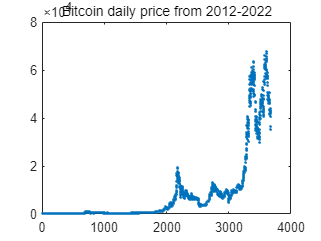

start_date_full = date_fixed(end);
%to prevent non-positive value, get the date_fixed(1)
%By my test, should still get the 20220122's position(or value)
end_date_full = date_fixed(end-10*365-23);
b_price_full = b_price(end_date_full:start_date_full);
dates_full = date_fixed(end_date_full:start_date_full);
dates_full = ((dates_full - dates_full(end))*(-1))+1;
plot (dates_full, b_price_full, '.')
title("Bitcoin daily price from 2012-2022")


%2020
start_date_2020 = alpha_date(end-8*365-2)

start_date_2020 = 20200101

end_date_2020 = alpha_date(end-9*365-2)

end_date_2020 = 20201231

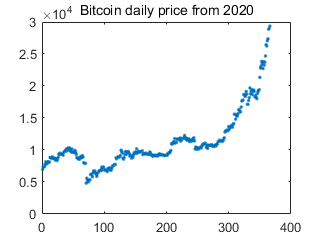

start_date_2020 = date_fixed(end-8*365-2);
end_date_2020 = date_fixed(end-9*365-2);
b_price_2020 = b_price(end_date_2020:start_date_2020);
dates_2020 = date_fixed(end_date_2020:start_date_2020);
dates_2020 = ((dates_2020 - dates_2020(end))*(-1)) + 1;
plot (dates_2020, b_price_2020, '.')
title("Bitcoin daily price from 2020")

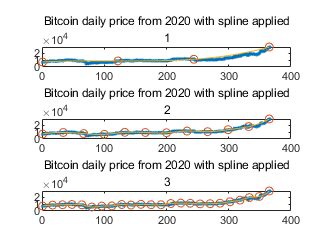


%spline
u = linspace(1,365,1000);
index = 1;
for n = [4,12,24]
    subplot(3,1,index);
    plot(dates_2020,b_price_2020,'.');
    hold on
    x = linspace(1,365,n);
    x = round(x);
    y = b_price_2020(x);
    x = (x-x(end))*(-1)+1;
    s = spline(x,y,u);
    plot(x,y,'o');
    plot(u,s);
    title("Bitcoin daily price from 2020 with spline applied",index);
    hold off
    index = index + 1;
end

Write your Observations for Problem 4 here

As my observations, as the n increase, the predict is more stablely correct, when it become n = 12, it look like all the points are hitting, when n = 24, the point is hitting all the lane, the n =24 is the best. If we increase the n, the prediction will be more preciece.

## Functions

### polyinterp.m

function v = polyinterp(x,y,u)
    %POLYINTERP  Polynomial interpolation.
    %   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
    %   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

    % Use Lagrangian representation.
    % Evaluate at all elements of u simultaneously.

    n = length(x);
    v = zeros(size(u));
    for k = 1:n
        w = ones(size(u));
        for j = [1:k-1 k+1:n]
            w = (u-x(j))./(x(k)-x(j)).*w;
        end
        v = v + w*y(k);
    end
end


### random_poly.m

function f = random_poly
    %RANDOM_POLY  Creates a random polynomial and returns that polynomial as a symbolic function.
    syms f x
    % Define some random coefficients
    r = rand(10); 
    
    % Create a random polynomial function
    f = r(1)*x^r(2) *sin(20*r(3) *x^r(4))  + ...
        r(5)*x^r(6) *cos(12*r(7) *x^r(8)); 
end

#### Any functions that you create should be placed in this function section because in live scripts, all functions must be at the end.